clear;
clc;
addpath('/MATLAB Drive/Research/SLS_K_realization/structured_implementation/final code')
addpath('/MATLAB Drive/Research/SLS_K_realization/structured_implementation/final code/other functions')

## Problem Formulation

Here we will perform control synthesis and then structure the controller implementation for a system to control the water level of dams along a river. The plant is given by

$\left[\begin{array}{ccc}x_1^+\\x_2^+\\x_3^+\end{array}\right]= \underbrace{\left[\begin{array}{ccc}1-f_1&0&0\\f_1&1-f_2&0\\0&f_2&1-f_3\end{array}\right]}_{A} \left[\begin{array}{c}x_1\\x_2\\x_3\end{array}\right] + \underbrace{I}_{B_1}\left[\begin{array}{c}w_1\\w_2\\w_3\end{array}\right] + \underbrace{\left[\begin{array}{ccc}-e_1&0&0\\e_1&-e_2&0\\0&e_2&-e_3\end{array}\right]}_{B_2} \left[\begin{array}{c}u_1\\u_2\\u_3\end{array}\right]$,

where $x_1,x_2,x_3$ are errors between water heights and reference values, $f_1,f_2,f_3$ are flow constants for each spatial site and $e_1,e_2,e_3$ are the efficiencies of three actuators.

As per [Rantzer 2019](https://arxiv.org/pdf/1812.07748), we use $f_1=0.1$, $f_2=0.2$, $f_3=0.3$ and $e_i=1~\forall i$.

f1 = 0.9; f2 = 0.8; f3 = 0.7;
e1 = 1; e2 = 1; e3 = 1;

A = [1-f1,0,0;
    f1,1-f2,0;
    0,f2,1-f3];
B2 = [-e1,0,0;
    e1,-e2,0;
    0,e2,e3];

Since $x$ is an error signal, we use the following cost function:

$z = \underbrace{\left[\begin{array}{ccc}I\\0\end{array}\right]}_{C_1}x + \underbrace{\left[\begin{array}{c}0\\\gamma I\end{array}\right]}_{D_{12}}u$.

gamma = 1;
C1 = [eye(3);zeros(3)]; D12 = [zeros(3);gamma*eye(3)];

The stabilizing controller set is

$\mathcal{C}_{\rm stab.} = \big\{K=\Phi^u(\Phi^x)^{-1}~|~(zI-A)\Phi^x-B_2\Phi^u=I~{\rm and}~\Phi^x,\Phi^u\in\mathcal{RH}_\infty\big\}$.

The optimal control problem is then


$$\inf_{\Phi^u,\Phi^x} \|C_1\Phi^x+D_{12}\Phi^u \|_{\mathcal{H}_2}$$



$${\rm s.t.}~~\Phi^x,\Phi^u\in\mathcal{C}_{\rm struc.}$$



$$~~~~~~~(\Phi^x,\Phi^u)\in\mathcal{C}_{\rm stab.}$$


where $\mathcal{C}_{\rm struc.}$ is a subspace constraint we impose on the closed-loop responses to give the controller a desired structure.

The constraints on this problem means that this optimization problem cannot be directly solved by Matlab's $\texttt{h2syn}$. We need to perform a "model match" to express this optimization problem in the form


$$\inf_{\tilde{K}} \|\tilde{P}_{11}+\tilde{P}_{12}\tilde{K}(I-\tilde{P}_{22}\tilde{K})^{-1}\tilde{P}_{21}\|_{\mathcal{H}_2}$$


which has no constraints on the decision variable $\tilde{K}$. In other words, we need to find a pseudoplant $\left[\begin{array}{cc}\tilde{P}_{11}&\tilde{P}_{12}\\\tilde{P}_{21}&\tilde{P}_{22}\end{array}\right]$ which, when feedback interconnected with $\tilde{K}$, will have the same $w\mapsto z$ norm as $C_1\Phi^x+D_{12}\Phi^u$.

## Controller Choice 1

We would like to have a controller with structure $\mathcal{C}_{\rm struc.}$ where


$$\mathcal{C}_{\rm struc.} = \Big\{ H(s)~|~{\rm sp}(H) = \left[\begin{array}{ccc}1&0&0\\1&1&0\\0&1&1\end{array}\right]\Big\}$$


However given that $\Phi^x$ and $\Phi^u$ are the closed-loop maps from disturbance $B_1w$ to $x$ and $u$ respectively, and all water flows downstream, its unreasonable to expect that we can enforce that a disturbance at site 1 never reaches site 3. Therefore we will instead use 

$\mathcal{C}_{\rm struc.} = \Big\{ H(s)~|~{\rm sp}(H) = \left[\begin{array}{ccc}1&0&0\\1&1&0\\1&1&1\end{array}\right]\Big\}$.

Since $\Phi^x,\Phi^u\in\mathcal{C}_{\rm struc.}$,

$\Phi^x=\left[\begin{array}{ccc}x_{11}&0&0\\x_{21}&x_{22}&0\\x_{31}&x_{32}&x_{33}\end{array}\right],~\Phi^u=\left[\begin{array}{ccc}u_{11}&0&0\\u_{21}&u_{22}&0\\u_{31}&u_{32}&u_{33}\end{array}\right]$.

Since $(\Phi^x,\Phi^u)\in\mathcal{C}_{\rm stab.}$, $(\Phi^x,\Phi^u)$ satisfies the affine subspace constraint $(zI-A)\Phi^x-B_2\Phi^u=I$.

These two constraints combined will give us equations directly on the scalar transfer functions $x_{:}$ and $u_{:}$.

syms x11 x21 x22 x31 x32 x33 u11 u21 u22 u31 u32 u33 z
Phix = [x11,0,0;x21,x22,0;x31,x32,x33]; Phiu = [u11,0,0;u21,u22,0;u31,u32,u33];
M = (z*eye(3)-A)*Phix - B2*Phiu

$$M = \left(\begin{array}{ccc} u_{11}+x_{11}\,\left(z-\frac{1}{10}\right) & 0 & 0\\ u_{21}-u_{11}-\frac{9\,x_{11}}{10}+x_{21}\,\left(z-\frac{1}{5}\right) & u_{22}+x_{22}\,\left(z-\frac{1}{5}\right) & 0\\ x_{31}\,\left(z-\frac{3}{10}\right)-u_{31}-\frac{4\,x_{21}}{5}-u_{21} & x_{32}\,\left(z-\frac{3}{10}\right)-u_{32}-\frac{4\,x_{22}}{5}-u_{22} & x_{33}\,\left(z-\frac{3}{10}\right)-u_{33} \end{array}\right)$$

This should be equal to $I$. Define $\phi:=\left[\begin{array}{cccccccccc}x_{11}&x_{21}&x_{22}&x_{31}&x_{32}&x_{33}&u_{11}&u_{21}&u_{22}&u_{31}&u_{32}&u_{33}\end{array}\right]^T$. We define $Q$ and $v$ such that the linear system $Q\phi=v$ encodes the stabilizing controller set affine subspace constraint ($M=I$).

J = transpose(M-eye(3));
eqns = J(:) == 0;
eqns([2,3,6]) = []; % 0 == 0 equations
[Q, v] = equationsToMatrix(eqns, [x11 x21 x22 x31 x32 x33 u11 u21 u22 u31 u32 u33]);

Any $\phi$ which gives $(x_{:},u_{:})$ that result in a stabilizing pair $(\Phi^x,\Phi^u)$ will satisfy $Q\phi=v$, meaning $\phi$ will be the sum of a particular solution (given by $\phi_p=Q^+v$) and any linear combination of vectors in the nullspace of $Q$.

phip = Q\v;

N = null(Q);

$N$ is the concatenation of column vectors $n_1,n_2,n_3,n_4,n_5,n_6$ which are the nullspace of $Q$. Then $\phi=\phi_p+\sum_{i=1}^6k_in_i$. The coeffecients $\{k_1,k_2,k_3,k_4,k_5,k_6\}$ are degrees of freedom, so they will be the decision variables in the unconstrained optimization problem, i.e $\tilde{K}=\left[\begin{array}{cccccc}k_1&k_2&k_3&k_4&k_5&k_6\end{array}\right]^T$. Then $\phi=\phi_p+N\tilde{K$.

To perform a model match, we hope to find $\tilde{P}_{11},\tilde{P}_{12},\tilde{P}_{21},\tilde{P}_{22}$ such that

$\|\tilde{P}_{11}+\tilde{P}_{12}\tilde{K}(I-\tilde{P}_{22}\tilde{K})^{-1}\tilde{P}_{21}\|_{\mathcal{H}_2} = \|C_1\Phi^x+D_{12}\Phi^u\|_{\mathcal{H}_2}$.

The $\mathcal{H}_2$ norm of a transfer matrix $H$ is an integral over ${\rm trace}(H^{\dagger}H)$. For $H=C_1\Phi^x+D_{12}\Phi^u$, lets examine how ${\rm trace}(H^{\dagger}H)$ depends on $x_{:}$ and $u_{:}$.

H = C1*Phix + D12*Phiu;
trace(H'*H)

$$ans = u_{11}\,\bar{u_{11}}+u_{21}\,\bar{u_{21}}+u_{22}\,\bar{u_{22}}+u_{31}\,\bar{u_{31}}+u_{32}\,\bar{u_{32}}+u_{33}\,\bar{u_{33}}+x_{11}\,\bar{x_{11}}+x_{21}\,\bar{x_{21}}+x_{22}\,\bar{x_{22}}+x_{31}\,\bar{x_{31}}+x_{32}\,\bar{x_{32}}+x_{33}\,\bar{x_{33}}$$

For our chosen cost function, conveniently, ${\rm trace}(H^{\dagger}H)=\phi^\dagger\phi=(\phi_p+N\tilde{K})^{\dagger}(\phi_p+N\tilde{K})$. Notice that if we let $\tilde{P}_{22}=0$ and $\tilde{P}_{21}=I$, then the trace() expression of the model matched system will be $(\tilde{P}_{11}+\tilde{P}_{12}\tilde{K})^{\dagger}(\tilde{P}_{11}+\tilde{P}_{12}\tilde{K})$. Then by letting $\tilde{P}_{11}=\phi_p$ and $\tilde{P}_{12}=N$ we will have achieved a model match.

tilP11 = sym2tf(phip,z); tilP12 = sym2tf(N,z); tilP21 = tf([1],[1]); tilP22 = zeros(1,6)*tf([0],[1]);

Now we use $\texttt{h2syn}$ to synthesize the optimal controller.

Ptil = [tilP11,tilP12;tilP21,tilP22];
nmeas = 1; ncont = 6;
[Ktil,~,cost1] = h2syn(Ptil,nmeas,ncont)

Ktil =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14         x15         x16         x17         x18         x19         x20         x21         x22
   x1      0.06577     0.04051    0.003672     -0.0155    -0.00564    -0.01902  -5.391e-17   -0.000272     0.01208   -0.000448    0.006834    -0.01342   0.0004688   -0.008235   -0.003807    0.009778   1.171e-16   2.125e-16   1.005e-16  -1.653e-16    2.77e-17  -2.394e-17
   x2            0         0.3       -0.16           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
   x3            0       0.125           0           0           0           0           0           0           0           0           0           0           0         

cost1 = 1.4763

We now use $\tilde{K}$ to recover $x_{:}$ and $u_{:}$ and therefore $\Phi^x$ and $\Phi^u$.

Ktil = minreal(tf(Ktil));
phi = sym2tf(phip,z) + sym2tf(N,z)*Ktil;
Phix = [phi(1),0,0;
        phi(2),phi(3),0;
        phi(4),phi(5),phi(6)];
Phiu = [phi(7),0,0;
        phi(8),phi(9),0;
        phi(10),phi(11),phi(12)];

We now use $\texttt{structuredControllerRealization.m}$ to generate a sparse realization of the optimal controller.

partition_x = ones(1,3); partition_u = ones(1,3);
[K,partition_ksi] = structuredControllerRealization(Phix,Phiu,partition_x,partition_u);

Test to ensure the structured controller is triangular.

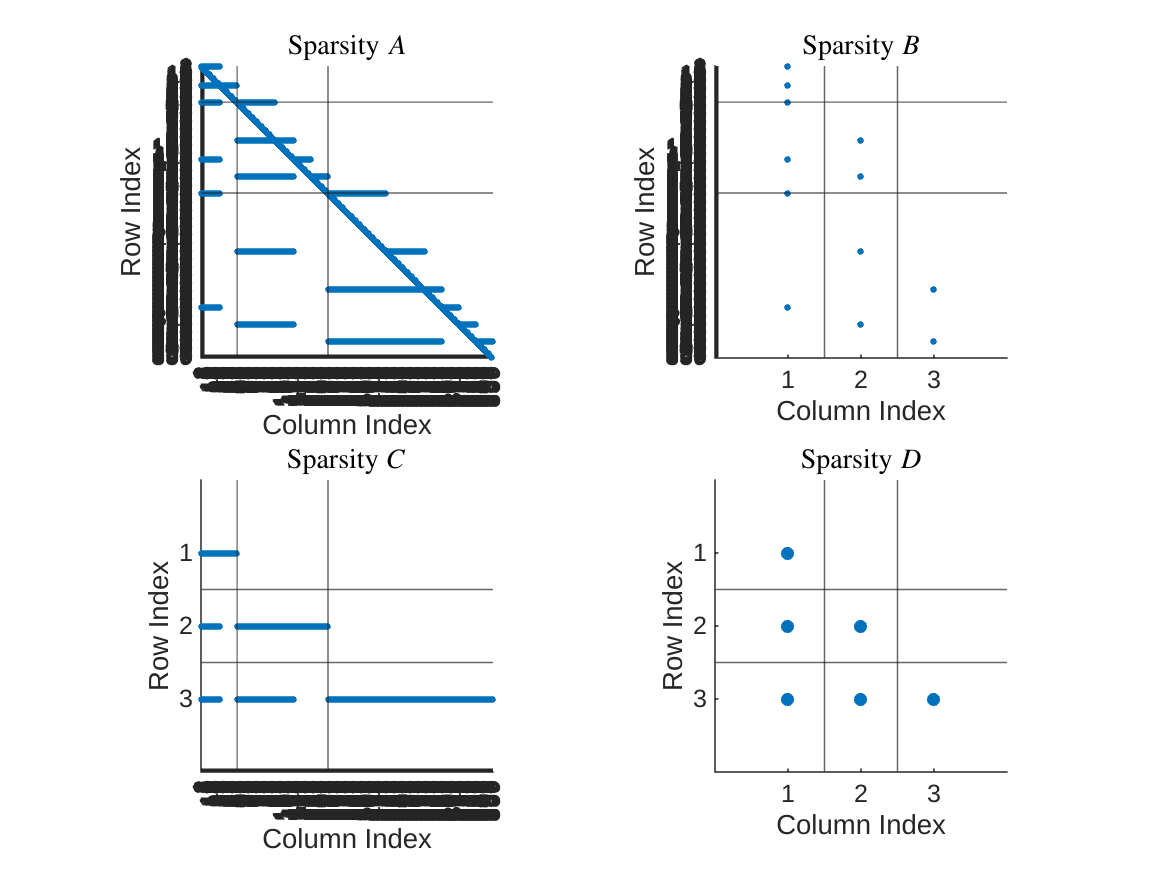

pltBlkSpstyRlztn(K,partition_ksi,partition_x,partition_u)

## Controller Choice 2

Perhaps it is too loose to allow any upper triangular closed-loop response. Maybe we also want to enforce that a disturbance at site 1 will take at least one time step to reach site 2 and at least two time steps to reach site 3. This is equivalent to enforcing that $\Phi^{x}$ and $\Phi^u$ have the form

$\Phi^x = \left[\begin{array}{ccc}x_{11}&0&0\\z^{-1}x_{21}&x_{22}&0\\z^{-2}x_{31}&z^{-1}x_{32}&x_{33}\end{array}\right]$, $\Phi^u = \left[\begin{array}{ccc}u_{11}&0&0\\z^{-1}u_{21}&u_{22}&0\\z^{-2}u_{31}&z^{-1}u_{32}&u_{33}\end{array}\right]$

with $x_{:},u_{:}\in\mathcal{RH}_{\infty}$.

All the steps are the same as for the previous controller up to the model match.

syms x11 x21 x22 x31 x32 x33 u11 u21 u22 u31 u32 u33 z
Phix = [x11,0,0;x21/z,x22,0;x31/z^2,x32/z,x33]; Phiu = [u11,0,0;u21/z,u22,0;u31/z^2,u32/z,u33];
M = (z*eye(3)-A)*Phix - B2*Phiu;
J = transpose(M-eye(3));
eqns = J(:) == 0;
eqns([2,3,6]) = []; % 0 == 0 equations
[Q, v] = equationsToMatrix(eqns, [x11 x21 x22 x31 x32 x33 u11 u21 u22 u31 u32 u33]);
phip = Q\v;

N = null(Q);

The model match here will be different since ${\rm trace}(H^{\dagger}H)\neq\phi^{\dagger}\phi$. Rather ${\rm trace}(H^{\dagger}H)=(R\phi)^{\dagger}R\phi$ where $R=\left[\begin{array}{cc}S&0\\0&S\end{array}\right]$ where$S={\rm diag}(1,z^{-1},1,z^{-2},z^{-1},1)$. The cost we're then hoping to optimize is $\|R\phi_p+RN\tilde{K}\|_{\mathcal{H}_2}$, which gives us the model matched plant as $\tilde{P}_{11}=R\phi_p$, $\tilde{P}_{12}=RN$, $\tilde{P}_{21}=1$, and $\tilde{P}_{22}=0$.

S = sym2tf(diag([1,1/z,1,1/z^2,1/z,1]),z);
R = blkdiag(S,S);
tilP11 = R*sym2tf(phip,z); tilP12 = R*sym2tf(N,z); tilP21 = tf([1],[1]); tilP22 = zeros(1,6)*tf([0],[1]);
Ptil = [tilP11,tilP12;tilP21,tilP22];
nmeas = 1; ncont = 6;
[Ktil,~,cost2] = h2syn(Ptil,nmeas,ncont)

Ktil =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14         x15         x16         x17         x18         x19         x20         x21         x22         x23         x24         x25         x26         x27         x28         x29         x30         x31         x32         x33         x34         x35         x36         x37         x38         x39         x40
   x1      0.07029      0.1246    0.001024  -2.563e-18    -0.04817   -0.003338  -2.435e-18    -0.07065   4.213e-16   4.605e-17     0.02669   0.0007773  -4.396e-05   7.385e-19   -5.11e-21      -0.011   -0.004175   0.0002268  -7.405e-18           0   -0.009237   -0.001428  -1.113e-17           0        0.02  -2.705e-16   1.661e-17   5.394e-16  -1.665e-16           0  -5.044e-17   2.729e-17           0   6.552e-18  -4.744e-17  -3.003e-17  -1.324e-17  -5.004e-17   3.094e-17   2.431e-17
   x2     

cost2 = 1.6258

[cost1,cost2]

ans =     1.4763    1.6258


As we should expect, the second cost is higher since the second structural constraint is more restrictive than the first.

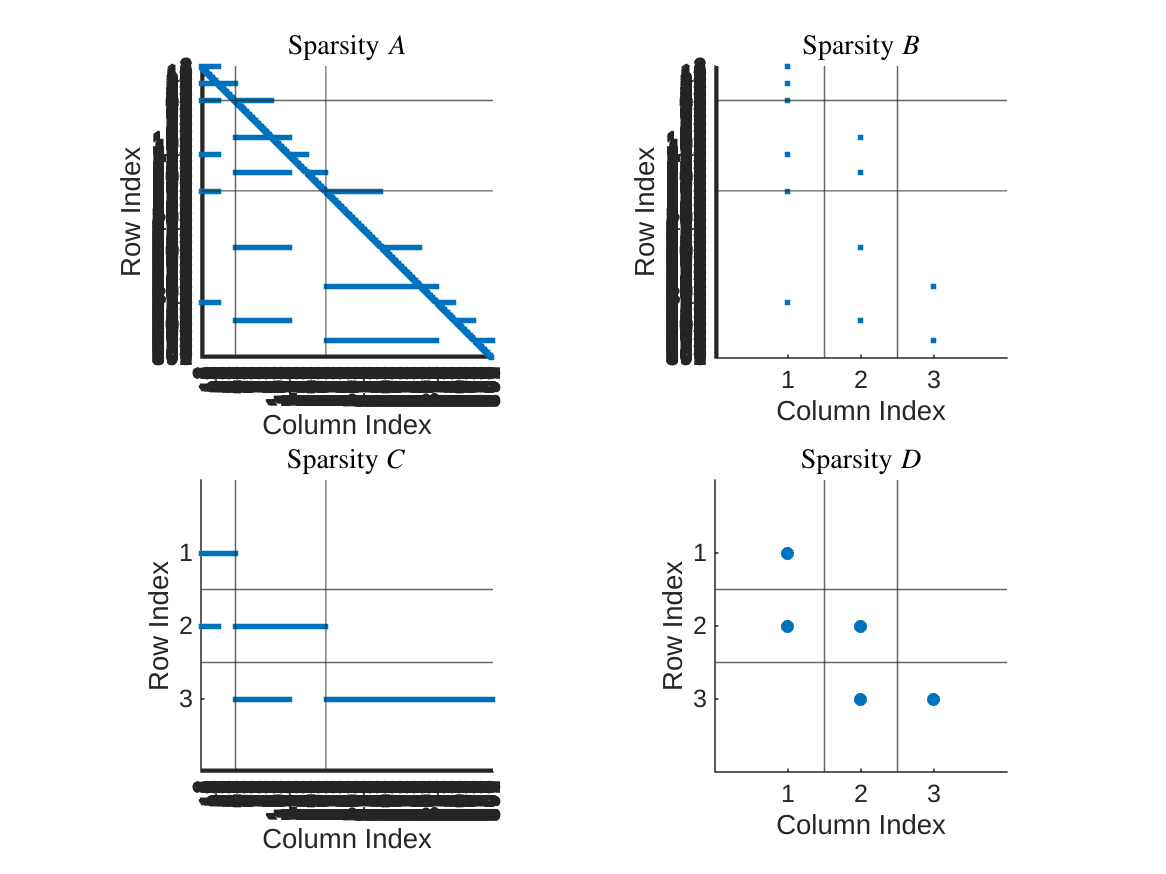

Ktil = minreal(tf(Ktil));
phi = sym2tf(phip,z) + sym2tf(N,z)*Ktil;
z = tf([1,0],1,phi.Ts);
Phix = [phi(1),0,0;
        phi(2)/z,phi(3),0;
        phi(4)/z^2,phi(5)/z,phi(6)];
Phiu = [phi(7),0,0;
        phi(8)/z,phi(9),0;
        phi(10)/z^2,phi(11)/z,phi(12)];
partition_x = ones(1,3); partition_u = ones(1,3);
[K,partition_ksi] = structuredControllerRealization(Phix,Phiu,partition_x,partition_u);
pltBlkSpstyRlztn(K,partition_ksi,partition_x,partition_u)

By enforcing that there is a two step delay between when a disturbance occurs at site 1 and when it reaches site 3, we have actually been able to construct a realization of $K$ where $C_K$ and $D_K$ have the original desired structure $\mathcal{A}$. This is an example which illustrates the tradeoff between communication length and performance discussed in [Jensen 2021](https://arxiv.org/pdf/2012.04792).